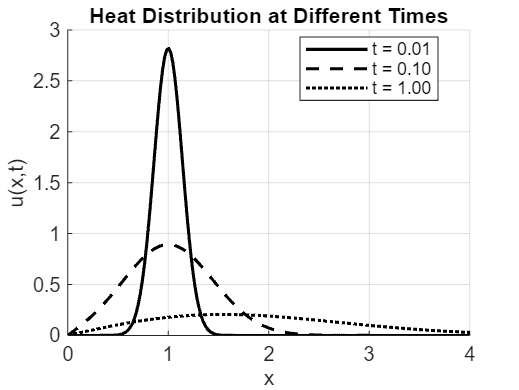

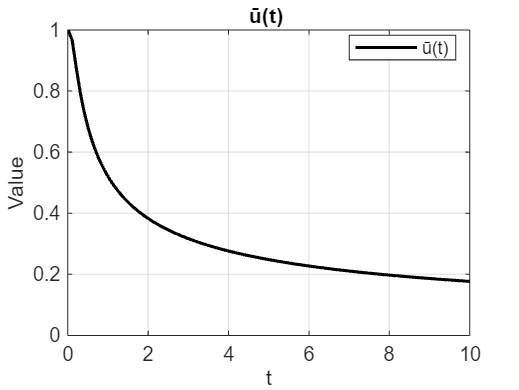

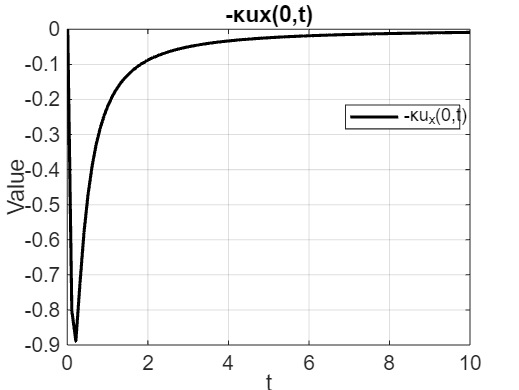

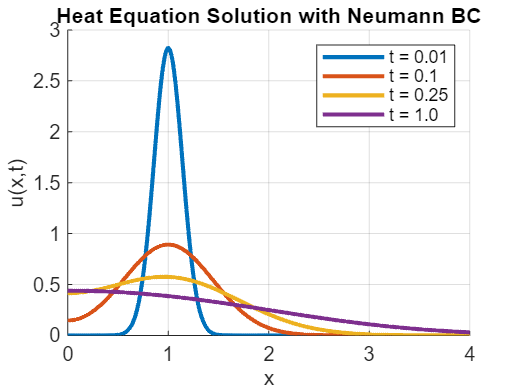

% Common parameters

kappa = 1;
x0 = 1;

%% Part (f): Plot u(x,t) at different times
figure(1);
x = linspace(0, 4, 200);  % x values from 0 to 4
t_values = [0.01, 0.1, 1.0];  % specified time values

% Function to calculate u(x,t)
u = @(x,t) (1./sqrt(4*pi*kappa*t)) .* (exp(-(x-x0).^2./(4*kappa*t)) - exp(-(x+x0).^2./(4*kappa*t)));

hold on;
% Plot for each time value with different line styles
plot(x, u(x,t_values(1)), '-k', 'LineWidth', 1.5);  % solid line
plot(x, u(x,t_values(2)), '--k', 'LineWidth', 1.5); % dashed line
plot(x, u(x,t_values(3)), ':k', 'LineWidth', 1.5);  % dotted line

% Add labels and legend
xlabel('x');
ylabel('u(x,t)');
title('Heat Distribution at Different Times');
legend(sprintf('t = %.2f', t_values(1)), ...
       sprintf('t = %.2f', t_values(2)), ...
       sprintf('t = %.2f', t_values(3)), ...
       'Location', 'best');
grid on;
hold off;

%% Part (g): Plot ū(t) and -κux(0,t)
figure(2);
t = linspace(0.01, 10, 100);  % time values (avoiding t=0)

% Calculate ū(t)
u_bar = erf(x0./sqrt(4*kappa*t));

% Calculate -κux(0,t)
ux_0 = -(x0./(t.*sqrt(4*pi*kappa*t))).*exp(-x0^2./(4*kappa*t));


% Plot both functions with different line styles
plot(t, u_bar, '-k', 'LineWidth', 1.5);     % solid line
xlabel('t');
ylabel('Value');
title('ū(t) ');
legend('ū(t)', 'Location', 'best');
grid on;



plot(t, ux_0, '-k', 'LineWidth', 1.5);     % dashed line

% Add labels and legend
xlabel('t');
ylabel('Value');
title('-κux(0,t)');
legend('-κu_x(0,t)', 'Location', 'best');
grid on;

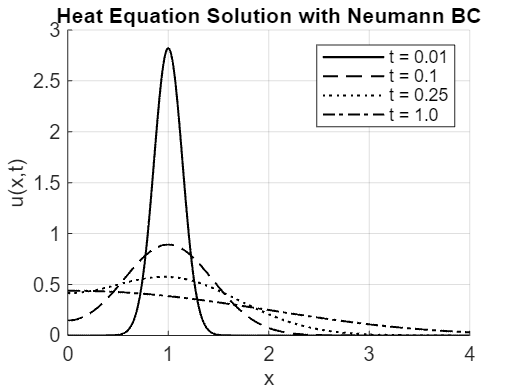

% Parameters
kappa = 1;
x0 = 1;
t_values = [0.01, 0.1, 0.25, 1.0];
x = linspace(0, 4, 1000);

% Define line styles for each plot
lineStyles = {'-', '--', ':', '-.'};

% Create figure
figure('Position', [100, 100, 800, 600])
hold on

% Plot for each time value with different line styles
for i = 1:length(t_values)
    t = t_values(i);
    u = 1/sqrt(4*pi*kappa*t) * (exp(-(x - x0).^2/(4*kappa*t)) + exp(-(x + x0).^2/(4*kappa*t)));
    plot(x, u, 'LineStyle', lineStyles{i}, 'Color', 'k', 'LineWidth', 1)
end

% Add labels and title
xlabel('x')
ylabel('u(x,t)')
title('Heat Equation Solution with Neumann BC')
legend('t = 0.01', 't = 0.1', 't = 0.25', 't = 1.0')
grid on

% Adjust axis for better visualization
ylim([0, 3])